# Figure 13B 

Coexpression of tDTom and ChAT

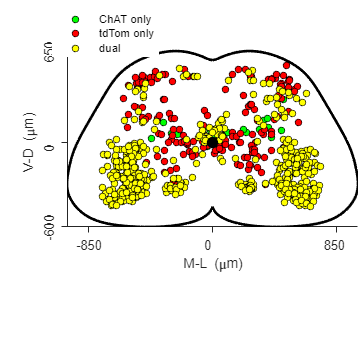

masterdir = 'F:\documents\master\data\';
clearvars -except masterdir
filename = 'fig13BC.xlsx';

data = readmatrix(filename,'Sheet','Sheet2');
datatable = readtable(filename,'Sheet','Sheet2');

% figure settings
lwconv = 2;   %line weidth  
inmarkersize= 5;
nr1 = 1;               % Number of rows in panel grid
nc1 = 1;               % Number of columns in panel grid
sizex1 = 5;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size



scp_raw = readmatrix('halfcordt.txt'); %transverse
lseg = [950,1000,950,900,850,800]; %corrected width for L6 to L1 segments 
    xl = [-1000,1000];
    yl = [-600,650];
    % scale spinal cord profile scp_raw for plotting raw data 
   pp =scp_raw(:,2)>0;
   nn = scp_raw(:,2)<=0;
   y_cord_pos = 2*yl(2)*scp_raw(pp,2);
   y_cord_neg = -2*yl(1)*scp_raw(nn,2);
   y_cord = vertcat(y_cord_pos,y_cord_neg);
   scp = horzcat(scp_raw(:,1),y_cord);

chat = datatable(datatable.Label==1,:);
tdtom = datatable(datatable.Label==2,:);
chat_tdtom = datatable(datatable.Label==3 | datatable.Label==4,:);

n_chat = size(chat,1);
n_tdtom = size(tdtom,1);
n_chat_tdtom = size(chat_tdtom,1);

% OUTPUT FIGURE 1
f1 = figure;
set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)])
h = 0;

Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize); 
%Panels.tweak(1,[0.15,0.1],[0.9,0.9]);
Panels.tweak(1,[0.15,0.3],[0.9,0.9*1.36/2]);
%Panels.tweak(2,[0.1,0.2],[0.9,0.9]);


h = 1;
scprofile = Panels.setPanel(h);

  
plot(2*lseg(2)*scp(:,1),scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
  hold on
plot(-2*lseg(2)*scp(:,1),scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord

chatplot = plot(chat.Xscaled,-chat.Yscaled,'o', 'MarkerEdgeColor',...
                 [0,0,0],'MarkerFaceColor',[0,1,0],'MarkerSize',inmarkersize);
tdtomplot = plot(tdtom.Xscaled,-tdtom.Yscaled,'o', 'MarkerEdgeColor',...
                 [0,0,0],'MarkerFaceColor',[1,0,0],'MarkerSize',inmarkersize);
chattdtomplot = plot(chat_tdtom.Xscaled,-chat_tdtom.Yscaled,'o', 'MarkerEdgeColor',...
                 [0,0,0],'MarkerFaceColor',[1,1,0],'MarkerSize',inmarkersize);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)

ax = gca;
         set(ax,'xlim', xl,'ylim',ylim,...
             'XTick',[-850,0,850],'XTickLabel',[-850,0,850],...
             'YTick',[-600,0,650],'YTickLabel',[-600,0,650],'YTickLabelRotation',90)   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 -800];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];
          set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [-1200 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];

         ll = legend([chatplot, tdtomplot, chattdtomplot],{'ChAT only','tdTom only', 'dual'});
         set (ll, 'Position',[0.2 0.85 0.1875 0.1119], 'Box','off')
 box off


% h = 2;
% alpha=1;
% vennpanel = Panels.setPanel(h);
% [vennplot,settings] = venn([n_tdtom+n_chat_tdtom,n_chat+n_chat_tdtom],n_chat_tdtom,...
%     'FaceColor',{'r','g'},'FaceAlpha', {alpha,0.8});
% ax = gca;
% set(ax, 'xlim',[-20,20],'ylim',[-20,20]);
% text(-14,0,num2str(n_tdtom), 'FontSize', 12);
% text(0,0,num2str(n_chat_tdtom), 'FontSize', 12);
% text(16,0,num2str(n_chat), 'FontSize', 12);
% axis off

 Panels.addPanels();